# Guide l'utilisateur fSpice

© Frédéric Martinez 2021

## Introduction

fspice est une fonction pour Matlab permettant la résolution symbolique des circuits linéaires. Les circuits qui peuvent être traités avec fspice peuvent contenir :

- Sources de tension et de courant indépendantes

- Sources de tension commandées en tension (VCVS)

- Sources de courant commandés en tension (VCCS)

- Résistances, Capacités, Inductances

- Amplificateur opérationnel idéal (modèle norateur-nullateur)

Les circuits sont traités dans le formaliste de la transformée de Laplace, avec s comme variable de Laplace

Cette fonction convertit le schéma fourni sous forme de netlist en un système d'équations linéaires suivant la méthode MNA.

Tous les détails sur cette méthode sont disponibles sur le cours Moodle : [https://moodle.umontpellier.fr/course/view.php?id=23180](https://moodle.umontpellier.fr/course/view.php?id=23180)

## Prise en Main : Circuit RC

Soit le circuit RC présenté sur la fig. 1. 

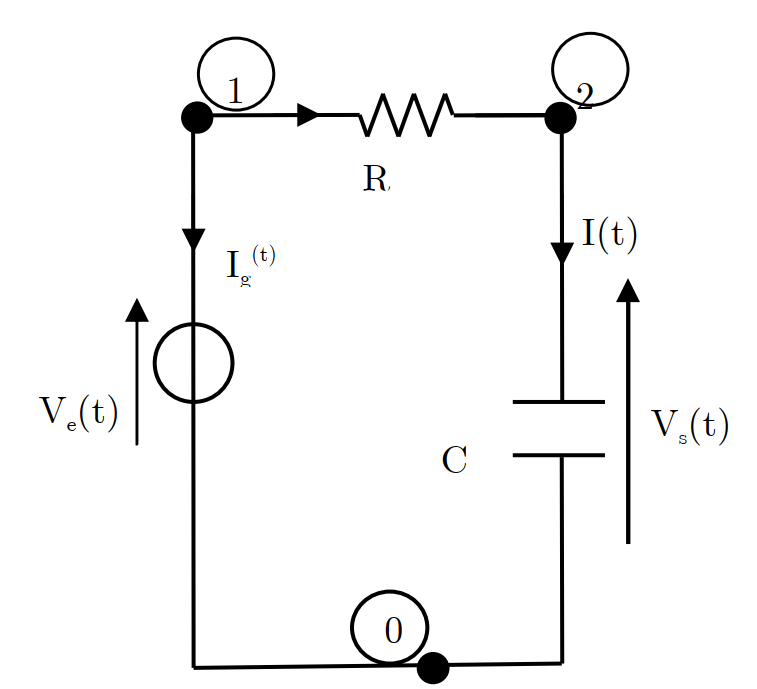

fig 1

La description du circuit se fait via la création d'une variable de type "cell". Cette variable cell comporte 1 colonne et autant de lignes que de composants : 

netlist={'Vsource1 1 0 Ve';'R1 1 2 R';'C1 2 0 C'}

netlist = 3×1 cell array
    {'Vsource1 1 0 Ve'}
    {'R1 1 2 R'       }
    {'C1 2 0 C'       }


Chaque élément de la variable 'netlist' est une chaine de caractères, décrivant le composant. 

Pour la source de tension indépendante, la syntaxe est la suivante :

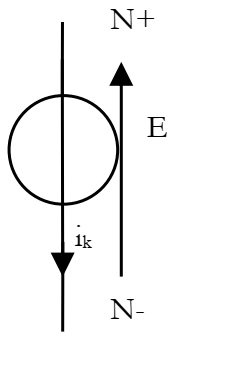

Vxxx N+ N- Valeur 

- xxx est une chaine alphanumérique identifiant le composant. Dans l'exemple du circuit RC, il s'agit de *source1*.

- N+ et N- sont les noeuds du circuit entre lesquels est insérée la source de tension. Dans l'exemple du circuit RC, N+ est le noeud 1, N- est le noeud 0.

- Valeur est la valeur de la source de tension indépendante. Dans l'exemple du circuit RC, il s'agit de la valeur *Ve*

Pour la résistance, la syntaxe est la suivante :

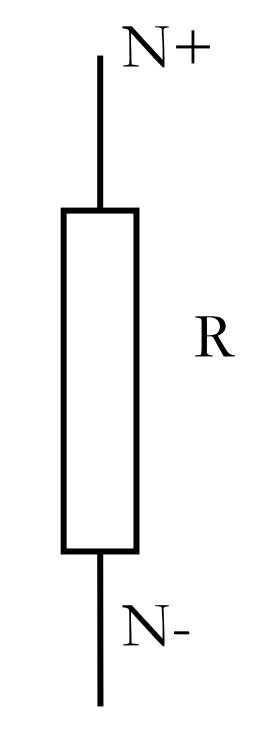

Rxxx N+ N- Valeur 

- xxx est une chaine alphanumérique identifiant le composant. Dans l'exemple du circuit RC, il s'agit de *1*.

- N+ et N- sont les noeuds du circuit entre lesquels est insérée la résistance. Dans l'exemple du circuit RC, N+ est le noeud 1, N- est le noeud 2.

- Valeur est la valeur de la résistance. Dans l'exemple du circuit RC, il s'agit de la valeur *R*.

Pour la Capacité, la syntaxe est la suivante :

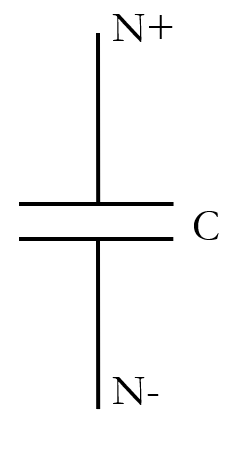

Cxxx N+ N- Valeur 

- xxx est une chaine alphanumérique identifiant le composant. Dans l'exemple du circuit RC, il s'agit de *1*.

- N+ et N- sont les noeuds du circuit entre lesquels est insérée la capacité. Dans l'exemple du circuit RC, N+ est le noeud 2, N- est le noeud 0.

- Valeur est la valeur de la capacité. Dans l'exemple du circuit RC, il s'agit de la valeur *C*.

La formulation MNA permet d'obtenir un système d'équation où le vecteur des inconnues est composé de l'ensemble des potentiels de noeuds et des courants débités par les sources de tensions indépendantes, sources de tensions contrôlées en tension et les amplificateurs opérationnels idéaux. La fonction fspice fournit ce vecteur inconnue, stocké dans la variable *X*, et la variable *name* indique la nature de chaque élément du vecteur X :

[X,name]=fspice(netlist)

** fspice 2.42  ** (c) Frederic Martinez


netlist = 3×1 cell array
    {'Vsource1 1 0 Ve'}
    {'R1 1 2 R'       }
    {'C1 2 0 C'       }


$$X = \left(\begin{array}{c} \mathrm{Ve}\\ \frac{\mathrm{Ve}}{C\,R\,s+1}\\ -\frac{C\,\mathrm{Ve}\,s}{C\,R\,s+1} \end{array}\right)$$

name = 1×3 cell array
    {'V(1)'}    {'V(2)'}    {'I(Vsource1)'}


La variable *name* indique que le 1er élément de X est le potentiel du noeud 1, que le 2ème élément est le potentiel du noeud 2 et que le 3ème élément est le courant débité par la source de tension, notée Ig sur la fig. 1.

Les noeuds indiqués dans la netlist sont des chaines alphanumériques. Cela permet, si besoin, de mettre des identifiants de noeuds plus explicites. Par exemple, on peut appeler le noeud 1 "in" et le noeud 2 "out" :

netlist={'Vsource1 in 0 Ve';'R1 in out R';'C1 out 0 C'}

netlist = 3×1 cell array
    {'Vsource1 in 0 Ve'}
    {'R1 in out R'     }
    {'C1 out 0 C'      }


[X,name]=fspice(netlist)

** fspice 2.42  ** (c) Frederic Martinez


netlist = 3×1 cell array
    {'Vsource1 in 0 Ve'}
    {'R1 in out R'     }
    {'C1 out 0 C'      }


$$X = \left(\begin{array}{c} \mathrm{Ve}\\ \frac{\mathrm{Ve}}{C\,R\,s+1}\\ -\frac{C\,\mathrm{Ve}\,s}{C\,R\,s+1} \end{array}\right)$$

name = 1×3 cell array
    {'V(in)'}    {'V(out)'}    {'I(Vsource1)'}


Attention : Le noeud 0, référence de potentiel du circuit, qui est égal à 0 Volt, ne peut être renommé.

La fonction de transfert, $H(p)=\frac{Vs(p)}{Ve(p)}$, est simplement le rapport des potentiels 2 et 1 :

H=X(2)/X(1)

$$H = \frac{1}{C\,R\,s+1}$$

### Réponse à un échelon :

On peut faire une application numérique, par exemple pour $R=1 k\Omega$ et $C=10 nF$, et calculer la réponse à un échelon.

R=1e3;C=10e-9;
syms s
vs=ilaplace(subs(H/s))

$$vs = 1-{\mathrm{e}}^{-100000\,t}$$

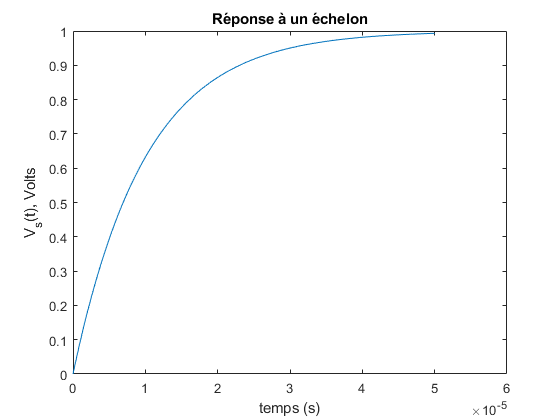

t=linspace(0,5*R*C,1000);
plot(t,subs(vs))
xlabel('temps (s)')
ylabel('V_s(t), Volts')
title('Réponse à un échelon')

### Diagramme de Bode

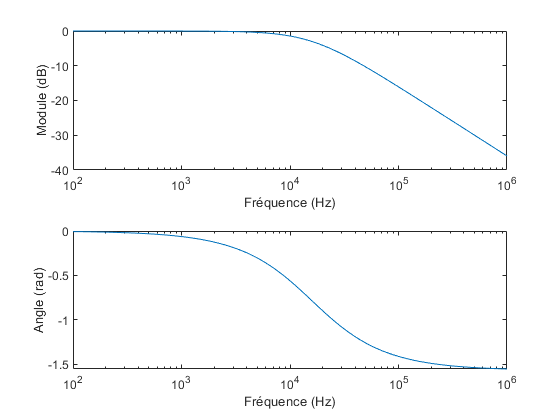

R=1e3;C=10e-9;
f=logspace(2,6,100);
s=2*pi*f*i;
subplot(2,1,1)
semilogx(f,20*log10(abs(subs(H))))
xlabel('Fréquence (Hz)')
ylabel('Module (dB)')
subplot(2,1,2)
semilogx(f,angle(subs(H)))
xlabel('Fréquence (Hz)')
ylabel('Angle (rad)')

## Exemples

### Cellule de Sallen Key 1

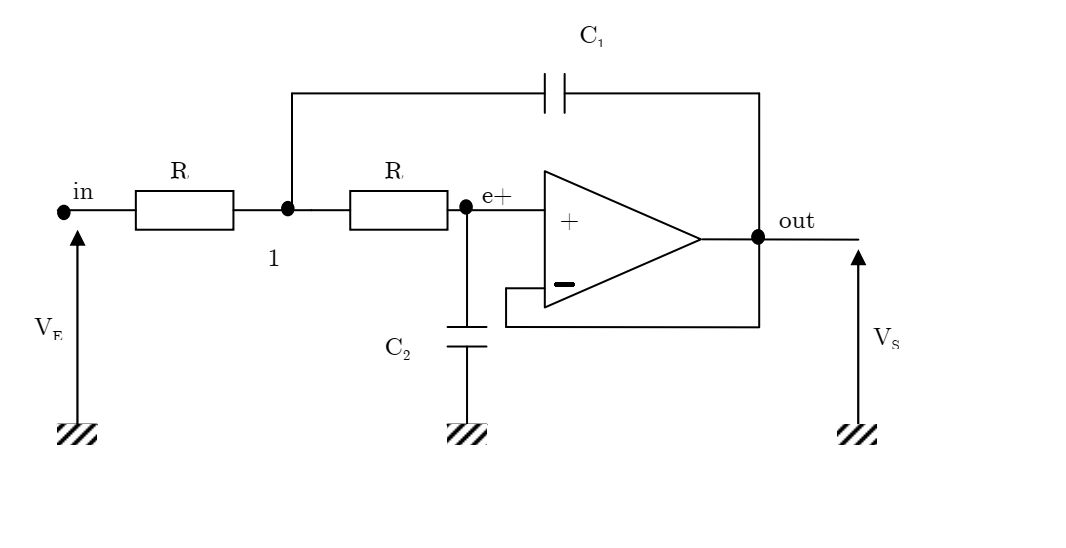

La syntaxe pour l'amplificateur opérationnel idéal est :

Xxxx N+ N- S avec N+ et N- les noeuds de l'entrée non-inverseuse et de l'entrée inverseuse, S le noeud de sortie de l'amplificateur opérationnel idéal.

netlist={'R1 in 1 R'
    'R2 1 e+ R'
    'C1 e+ 0 C1'
    'C2 1 out C2'
    'X1 e+ out out'
    'V1 in 0 Ve'};
[X name]=fspice(netlist)

** fspice 2.42  ** (c) Frederic Martinez


netlist = 6×1 cell array
    {'R1 in 1 R'    }
    {'R2 1 e+ R'    }
    {'C1 e+ 0 C1'   }
    {'C2 1 out C2'  }
    {'X1 e+ out out'}
    {'V1 in 0 Ve'   }


$$X = \begin{array}{l} \left(\begin{array}{c} \frac{\mathrm{Ve}\,\left(C_{1}\,R\,s+1\right)}{\sigma_{1}}\\ \frac{\mathrm{Ve}}{\sigma_{1}}\\ \mathrm{Ve}\\ \frac{\mathrm{Ve}}{\sigma_{1}}\\ \frac{C_{1}\,C_{2}\,R\,\mathrm{Ve}\,s^{2}}{\sigma_{1}}\\ -\frac{C_{1}\,\mathrm{Ve}\,s\,\left(C_{2}\,R\,s+1\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=C_{1}\,C_{2}\,R^{2}\,s^{2}+2\,C_{1}\,R\,s+1 \end{array}$$

name = 1×6 cell array
    {'V(1)'}    {'V(e+)'}    {'V(in)'}    {'V(out)'}    {'I(X1)'}    {'I(V1)'}


NB: l'utilisation d'un amplificateur opérationnel ajoute le courant débité par ce composant (noté rentrant), dans le vecteur des inconnues, ici en 5ème position.

La fonction de transfert est :

H=X(4)/X(3)

$$H = \frac{1}{C_{1}\,C_{2}\,R^{2}\,s^{2}+2\,C_{1}\,R\,s+1}$$

### Cellule de Sallen Key 2

Dans cet exemple, l'amplificateur opérationnel est modélisé par une source de tension commandée en tension (VCVS), avec comme fonction de transfert en boucle ouverte un modèle à pôle dominant $H_{BO}(p)=\frac{A_0}{1+\tau p}$.

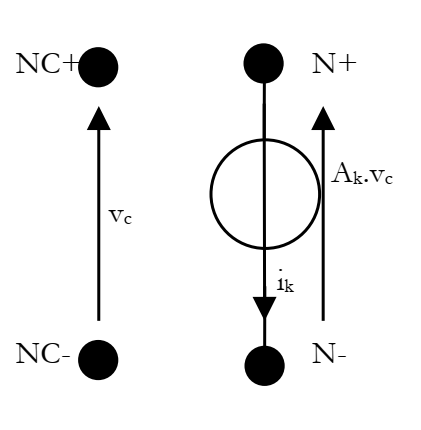

Syntaxe VCVS : Exxx N+ N- NC+ NC- Ak

netlist={'R1 in 1 R'
    'R2 1 e+ R'
    'C1 e+ 0 C1'
    'C2 1 out C2'
    'E1 out 0 e+ out A0/(1+tau*s)'
    'V1 in 0 Ve'};
[X name]=fspice(netlist)

** fspice 2.42  ** (c) Frederic Martinez


netlist = 6×1 cell array
    {'R1 in 1 R'                   }
    {'R2 1 e+ R'                   }
    {'C1 e+ 0 C1'                  }
    {'C2 1 out C2'                 }
    {'E1 out 0 e+ out A0/(1+tau*s)'}
    {'V1 in 0 Ve'                  }


$$X = \begin{array}{l} \left(\begin{array}{c} \frac{\mathrm{Ve}\,\left(A_{0}+s\,\tau +C_{1}\,R\,s+\sigma_{2}+A_{0}\,C_{1}\,R\,s+1\right)}{\sigma_{1}}\\ \frac{\mathrm{Ve}\,\left(A_{0}+s\,\tau +1\right)}{\sigma_{1}}\\ \mathrm{Ve}\\ \frac{A_{0}\,\mathrm{Ve}}{\sigma_{1}}\\ \frac{C_{2}\,\mathrm{Ve}\,s\,\left(s\,\tau +C_{1}\,R\,s+\sigma_{2}+A_{0}\,C_{1}\,R\,s+1\right)}{\sigma_{1}}\\ -\frac{\mathrm{Ve}\,s\,\left(C_{1}+C_{2}+A_{0}\,C_{1}+C_{1}\,s\,\tau +C_{2}\,s\,\tau +C_{1}\,C_{2}\,R\,s+C_{1}\,C_{2}\,R\,s^{2}\,\tau +A_{0}\,C_{1}\,C_{2}\,R\,s\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=A_{0}+s\,\tau +2\,C_{1}\,R\,s+C_{2}\,R\,s+2\,C_{1}\,R\,s^{2}\,\tau +C_{2}\,R\,s^{2}\,\tau +C_{1}\,C_{2}\,R^{2}\,s^{2}+2\,A_{0}\,C_{1}\,R\,s+A_{0}\,C_{1}\,C_{2}\,R^{2}\,s^{2}+C_{1}\,C_{2}\,R^{2}\,s^{3}\,\tau +1\\ \sigma_{2}=C_{1}\,R\,s^{2}\,\tau \end{array}$$

name = 1×6 cell array
    {'V(1)'}    {'V(e+)'}    {'V(in)'}    {'V(out)'}    {'I(E1)'}    {'I(V1)'}


La fonction de transfert est :

H1=X(4)/X(3)

$$H1 = \frac{A_{0}}{A_{0}+s\,\tau +2\,C_{1}\,R\,s+C_{2}\,R\,s+2\,C_{1}\,R\,s^{2}\,\tau +C_{2}\,R\,s^{2}\,\tau +C_{1}\,C_{2}\,R^{2}\,s^{2}+2\,A_{0}\,C_{1}\,R\,s+A_{0}\,C_{1}\,C_{2}\,R^{2}\,s^{2}+C_{1}\,C_{2}\,R^{2}\,s^{3}\,\tau +1}$$

On remarque que si A→$\infty$, on retrouve la fonction de transfert obtenue avec l'AOP idéal :

syms A0
limit(H1,A0,inf)

$$ans = \frac{1}{C_{1}\,C_{2}\,R^{2}\,s^{2}+2\,C_{1}\,R\,s+1}$$

Voici un script qui permet de comparer très rapidement les réponses harmoniques pour une cellule de Sallen Key (R=1k$\Omega$, C1=8pF,C2=3.2nF) avec modèle d’AOP idéal ou AOP 1 pôle (A0=2e5, tau=1/2/pi/10) :

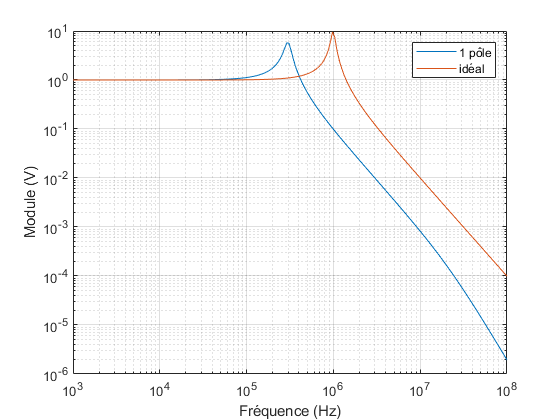

f=logspace(3,8,200);
s=2*pi*f*i;
R=1000;
C1=8e-12;
C2=3.2e-9;
A0=2e5;
tau=1/2/pi/10;

figure
loglog(f,abs(subs(H1)),f,abs(subs(H)))
grid
legend('1 pôle','idéal')
xlabel('Fréquence (Hz)')
ylabel('Module (V)')

### Analyse petit signal d’un montage Emetteur Commun

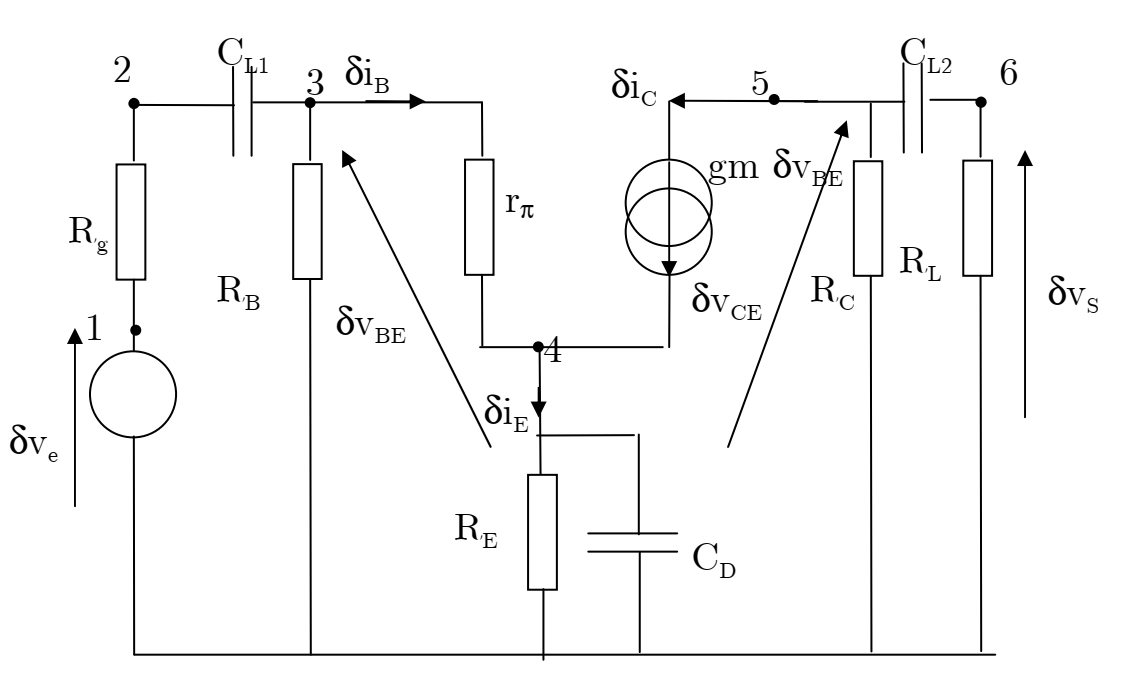

Ce circuit met en jeu un générateur de courant commandé en tension (VCCS).

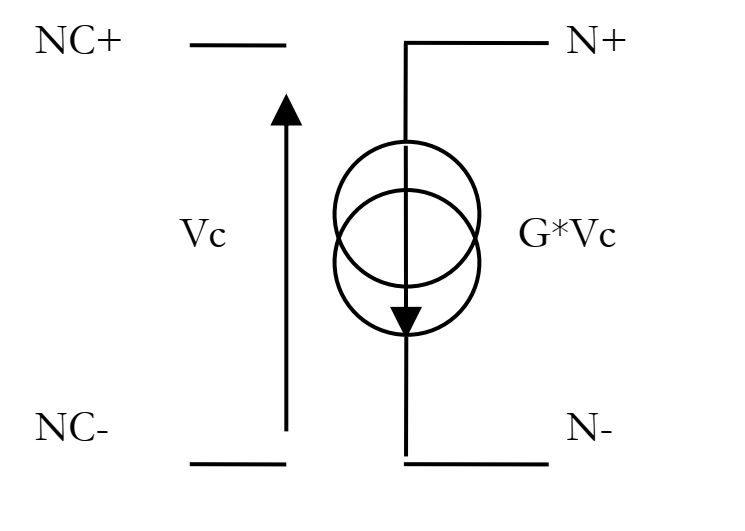

Syntaxe : Gxxx N+ N- NC+ NC- G

En prenant VCC=15V, b=200, RE=3.3 k$\Omega$, RC=3.3 k$\Omega$, RB=780 k$\Omega$, CL1=CL2=CD=470µF, RL=25 k$\Omega$, Rg=50 $\Omega$ et Ve(t)=0.001 sin(2$\pi$$\omega$ t),  on obtient facilement le module de l’amplitude complexe du nœud 6 :

netlist={'V1 1 0 ve'
    'R1 1 2 Rg'
    'C1 2 3 CL1'
    'R2 3 0 RB'
    'R3 3 4 rpi'
    'R4 4 0 RE'
    'C2 4 0 CD'
    'G1 5 4 3 4 gm'
    'R5 5 0 RC'
    'R6 6 0 RL'
    'C3 5 6 CL2'};
[X name]=fspice(netlist)

** fspice 2.42  ** (c) Frederic Martinez


netlist = 11×1 cell array
    {'V1 1 0 ve'    }
    {'R1 1 2 Rg'    }
    {'C1 2 3 CL1'   }
    {'R2 3 0 RB'    }
    {'R3 3 4 rpi'   }
    {'R4 4 0 RE'    }
    {'C2 4 0 CD'    }
    {'G1 5 4 3 4 gm'}
    {'R5 5 0 RC'    }
    {'R6 6 0 RL'    }
    {'C3 5 6 CL2'   }


name = 1×7 cell array
    {'V(1)'}    {'V(2)'}    {'V(3)'}    {'V(4)'}    {'V(5)'}    {'V(6)'}    {'I(V1)'}


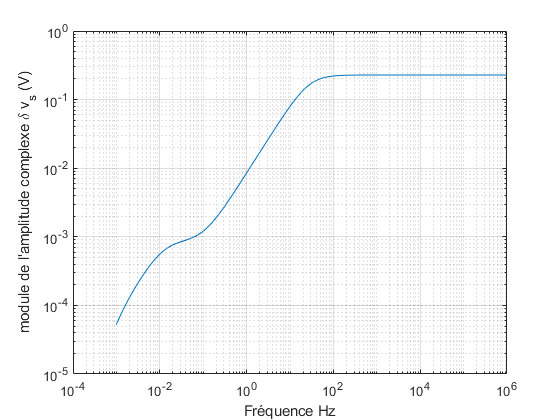

Rg=50;RE=3.3e3;RC=3.3e3;RB=780e3;CL1=470e-6;
CL2=CL1;CD=CL1;RL=25e3;rpi=2500;gm=200/rpi;
ve=.001;
f=logspace(-3,6,300);
s=2*pi*f*i;
figure
loglog(f,abs(subs(X(6))))  
xlabel('Fréquence (Hz)')
ylabel('module de l''amplitude complexe \delta v_s (V)')
grid